# BBC DRL Training

clear;
close all;
bdclose('all');
addpath("/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/model");

## Define Environment

Create the observation and action specifications for the environment using continuous observation and action spaces.

Ts = 0.01;
Tf = 5;
Ts_sample = Ts;
kinova_params;

numObs = 22;  % Number of observations
numAct = 2;   % Number of actions

obsInfo = rlNumericSpec([numObs 1]);

actInfo = rlNumericSpec([numAct 1]);
actInfo.LowerLimit = -1;
actInfo.UpperLimit = 1;

mdl = "BBC_RL_training";
blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

env.ResetFcn = @kinovaResetFcn;

## Create Agent

% Set the random seed for reproducibility.
% rng(0)

% Define the network layers.
cnet = [
    featureInputLayer(numObs,"Normalization","none","Name","observation")
    fullyConnectedLayer(128,"Name","fc1")
    concatenationLayer(1,2,"Name","concat")
    reluLayer("Name","relu1")
    fullyConnectedLayer(64,"Name","fc3")
    reluLayer("Name","relu2")
    fullyConnectedLayer(32,"Name","fc4")
    reluLayer("Name","relu3")
    fullyConnectedLayer(16,"Name","fc5")
    reluLayer("Name","relu4")
    fullyConnectedLayer(1,"Name","CriticOutput")];

actionPath = [
    featureInputLayer(numAct,"Normalization","none","Name","action")
    fullyConnectedLayer(128,"Name","fc2")];

% Connect the layers.
criticNetwork = layerGraph(cnet);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = connectLayers(criticNetwork,"fc2","concat/in2");
criticdlnet = dlnetwork(criticNetwork,'Initialize',false);

criticdlnet1 = initialize(criticdlnet);
% criticdlnet2 = initialize(criticdlnet);
critic1 = rlQValueFunction(criticdlnet1,obsInfo,actInfo, ...
    "ObservationInputNames","observation");
% critic2 = rlQValueFunction(criticdlnet2,obsInfo,actInfo, ...
%     "ObservationInputNames","observation");

% Create the actor network layers.
anet = [featureInputLayer(numObs,"Normalization","none","Name","State")
    fullyConnectedLayer(128, "Name","actorFC1")
    reluLayer("Name","relu1")
    fullyConnectedLayer(64,"Name","actorFC2")
    reluLayer("Name","relu2")
    fullyConnectedLayer(32,"Name","actorFC3")
    reluLayer("Name","relu3")
    fullyConnectedLayer(numAct,"Name","Action")
    tanhLayer("Name","tanh1")];

% Connect the layers.
actorNetwork = layerGraph(anet);
actordlnet = dlnetwork(actorNetwork);
actor = rlContinuousDeterministicActor(actordlnet, obsInfo, actInfo, ...
    "ObservationInputNames","State");

agentOpts = rlDDPGAgentOptions( ...
    "SampleTime",Ts, ...
    "TargetSmoothFactor",1e-3, ...    
    "ExperienceBufferLength",1e6, ...
    "MiniBatchSize",128, ...
    'NumStepsToLookAhead',1, ...
    "DiscountFactor",0.99);

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 1e-4;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;

agentOpts.CriticOptimizerOptions.Algorithm = "adam";
agentOpts.CriticOptimizerOptions.LearnRate = 1e-4;
agentOpts.CriticOptimizerOptions.GradientThreshold = 1;

% for ct = 1:2
%     agentOpts.CriticOptimizerOptions(ct).Algorithm = "adam";
%     agentOpts.CriticOptimizerOptions(ct).LearnRate = 1e-4;
%     agentOpts.CriticOptimizerOptions(ct).GradientThreshold = 1;
% end

agent = rlDDPGAgent(actor,critic1,agentOpts);

## Train Agent

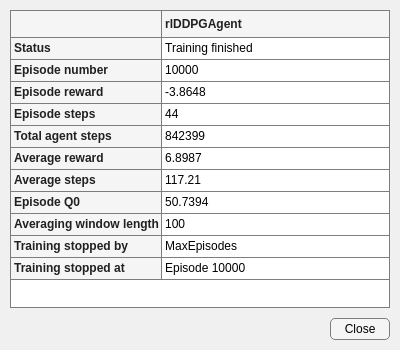

% reward weights for diff semantics
% default weights: [0.1, 1, 0.05]
plateWeight = 0.1;
ballWeight = 2;
stableWeight = 0.05;
rewardWeights = [plateWeight, ballWeight, stableWeight];
isTerminate = true;

trainOpts = rlTrainingOptions(...
    "MaxEpisodes", 10000, ...
    "MaxStepsPerEpisode", floor(Tf/Ts), ...
    "ScoreAveragingWindowLength", 100, ...
    "Plots", "training-progress", ...
    "StopTrainingCriteria", "AverageSteps", ...
    "StopTrainingValue", floor(Tf/Ts)*0.96, ...
    "UseParallel", false);

if trainOpts.UseParallel
    trainOpts.ParallelizationOptions.AttachedFiles = [pwd,filesep] + ...
        ["bracelet_with_vision_link.STL";
        "half_arm_2_link.STL";
        "end_effector_link.STL";
        "shoulder_link.STL";
        "base_link.STL";
        "forearm_link.STL";
        "spherical_wrist_1_link.STL";
        "bracelet_no_vision_link.STL";
        "half_arm_1_link.STL";
        "spherical_wrist_2_link.STL"];
end

doTraining = true;
if doTraining
    trainingStats = train(agent,env,trainOpts);
else
    load("kinovaBallBalanceAgent.mat")       
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    agentName = ['BBC-DDPG-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(rewardWeights(1))+...
        "-"+string(rewardWeights(2))+...
        "-"+string(rewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agent, ...
                 'rewardWeights', rewardWeights, ...
                 'agentOptions', agentOpts, ...
                 'criticNetwork', criticNet, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/DRL_training/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved');
end

## Simulate Trained Agent

To validate the trained agent, run the Simulink model.

Define an arbitrary initial position for the ball with respect to the plate center. To view the agent performance in different situations, change this to other locations on the plate.

% isTerminate = false;
maxsteps = Tf/Ts;
simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
[ball,R6_q0,R7_q0,U0] = BBC_ResetFun();
experiences = sim(env,agent,simOpts);

 
% state
x_ball = experiences.SimulationInfo.logsout.getElement('x_ball').Values.Data;
y_ball =  experiences.SimulationInfo.logsout.getElement('y_ball').Values.Data;
plate_yaw =  experiences.SimulationInfo.logsout.getElement('plate_yaw').Values.Data;
plate_pitch =  experiences.SimulationInfo.logsout.getElement('plate_pitch').Values.Data;
plate_roll =  experiences.SimulationInfo.logsout.getElement('plate_roll').Values.Data;
theta_J6 =  experiences.SimulationInfo.logsout.getElement('theta_J6').Values.Data;
theta_J7 =  experiences.SimulationInfo.logsout.getElement('theta_J7').Values.Data;
is_outside =  experiences.SimulationInfo.logsout.getElement('is_outside').Values.Data;
% action
torque_J6 =  experiences.SimulationInfo.logsout.getElement('torque_J6').Values.Data;
torque_J7 =  experiences.SimulationInfo.logsout.getElement('torque_J7').Values.Data;
% reward
plate_reward =  experiences.SimulationInfo.logsout.getElement('plate_reward').Values.Data;
ball_reward =  experiences.SimulationInfo.logsout.getElement('ball_reward').Values.Data;
stable_reward =  experiences.SimulationInfo.logsout.getElement('stable_reward').Values.Data;
final_reward =  experiences.SimulationInfo.logsout.getElement('final_reward').Values.Data;

steps = length(x_ball);
time = 0:Ts_sample:(steps-1)*Ts_sample;

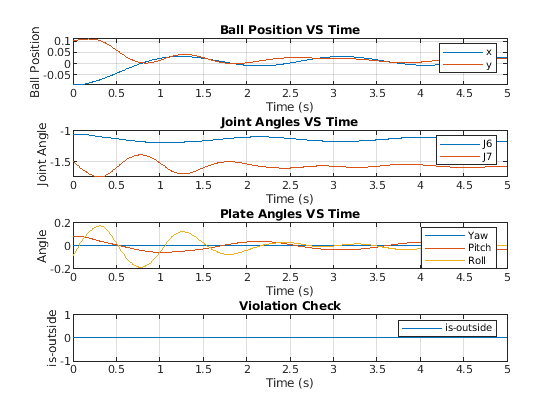


% plotting
figure(1);
subplot(4,1,1)
plot(time,x_ball, time,y_ball);
title('Ball Position VS Time');
legend('x', 'y');
xlabel('Time (s)');
ylabel('Ball Position');
grid on;

subplot(4,1,2)
plot(time,theta_J6, time,theta_J7);
title('Joint Angles VS Time');
legend('J6', 'J7');
xlabel('Time (s)');
ylabel('Joint Angle');
grid on;

subplot(4,1,3)
plot(time,plate_yaw, time,plate_pitch, time,plate_roll);
title('Plate Angles VS Time');
legend('Yaw', 'Pitch', 'Roll');
xlabel('Time (s)');
ylabel('Angle');
grid on;

subplot(4,1,4)
plot(time,is_outside);
title('Violation Check');
legend('is-outside');
xlabel('Time (s)');
ylabel('is-outside');
grid on;

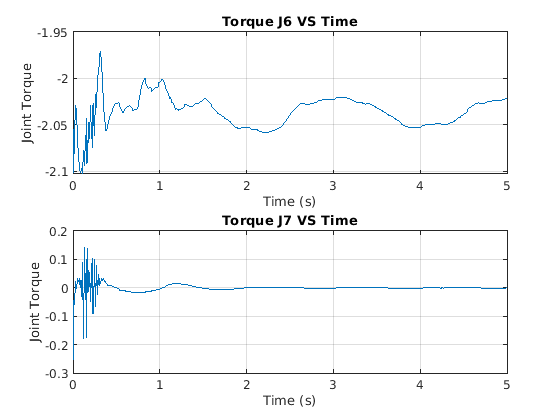


figure(2);
subplot(2,1,1)
plot(time,torque_J6);
title('Torque J6 VS Time');
xlabel('Time (s)');
ylabel('Joint Torque');
grid on;

subplot(2,1,2)
plot( time,torque_J7);
title('Torque J7 VS Time');
xlabel('Time (s)');
ylabel('Joint Torque');
grid on;

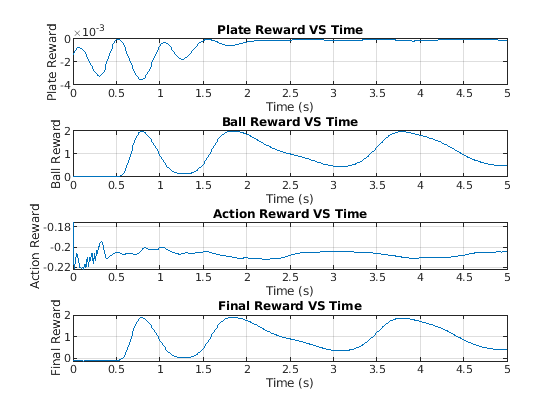


figure(3);
subplot(4,1,1)
plot(time,plate_reward);
title('Plate Reward VS Time');
xlabel('Time (s)');
ylabel('Plate Reward');
grid on;

subplot(4,1,2)
plot(time,ball_reward);
title('Ball Reward VS Time');
xlabel('Time (s)');
ylabel('Ball Reward');
grid on;

subplot(4,1,3)
plot(time,stable_reward);
title('Action Reward VS Time');
xlabel('Time (s)');
ylabel('Action Reward');
grid on;

subplot(4,1,4)
plot(time,final_reward);
title('Final Reward VS Time');
xlabel('Time (s)');
ylabel('Final Reward');
grid on;

## Training progress info

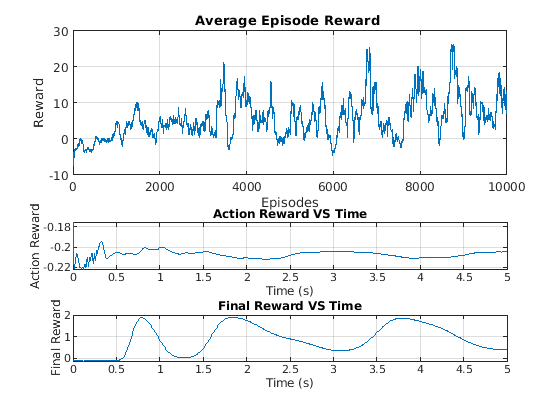

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(3);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

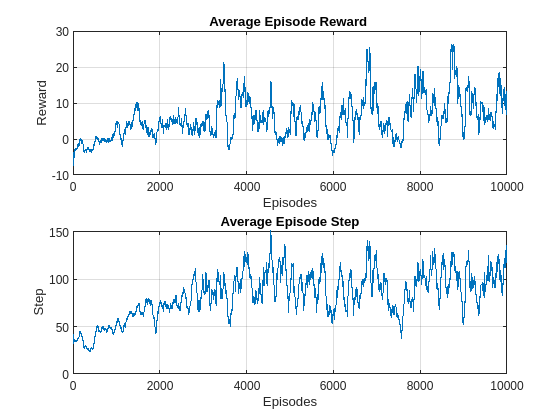


subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on

## Environment Reset Function

function in = kinovaResetFcn(in)
    % Ball parameters
    ball.radius = 0.02;     % m
    ball.mass   = 0.0027;   % kg
    ball.shell  = 0.0002;   % m
    
    % Calculate ball moment of inertia.
    ball.moi = calcMOI(ball.radius,ball.shell,ball.mass);
    
    % Initial conditions. +z is vertically upward.
    % Randomize the x and y distances within the plate.
    ball.x0  = -0.125 + 0.25*rand;  % m, initial x distance from plate center
    ball.y0  = -0.125 + 0.25*rand;  % m, initial y distance from plate center
    ball.z0  = ball.radius;         % m, initial z height from plate surface
    
    ball.dx0 = 0;   % m/s, ball initial x velocity
    ball.dy0 = 0;   % m/s, ball initial y velocity
    ball.dz0 = 0;   % m/s, ball initial z velocity
    
    % Contact friction parameters
    ball.staticfriction     = 0.5;
    ball.dynamicfriction    = 0.3; 
    ball.criticalvelocity   = 1e-3;
    
    % Convert coefficient of restitution to spring-damper parameters.
    coeff_restitution = 0.89;
    [k, c, w] = cor2SpringDamperParams(coeff_restitution,ball.mass);
    ball.stiffness = k;
    ball.damping = c;
    ball.transitionwidth = w;
    
    in = setVariable(in,"ball",ball);
    
    % Randomize joint angles within a range of +/- 5 deg from the 
    % starting positions of the joints.
    R6_q0 = deg2rad(-65) + deg2rad(-5+10*rand);
    R7_q0 = deg2rad(-90) + deg2rad(-5+10*rand);
    in = setVariable(in,"R6_q0",R6_q0);
    in = setVariable(in,"R7_q0",R7_q0);
    
    % Compute approximate initial joint torques that hold the ball,
    % plate and arm at their initial congifuration
    g = 9.80665;
    wrist_torque_0 = ...
        (-1.882 + ball.x0 * ball.mass * g) * cos(deg2rad(-65) - R6_q0);
    hand_torque_0 = ...
        (0.0002349 - ball.y0 * ball.mass * g) * cos(deg2rad(-90) - R7_q0);
    U0 = [wrist_torque_0 hand_torque_0];
    in = setVariable(in,"U0",U0);

    % Animation
%     in = setPostSimFcn(in, @animatedPath);
end
